## 8.5   符号微积分

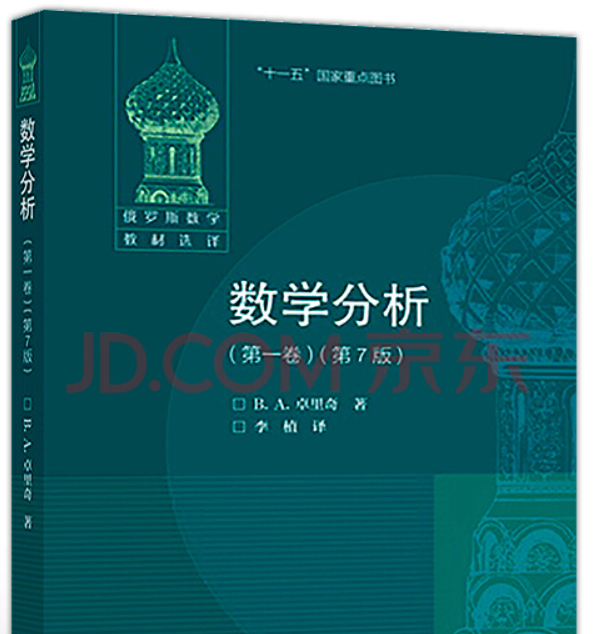

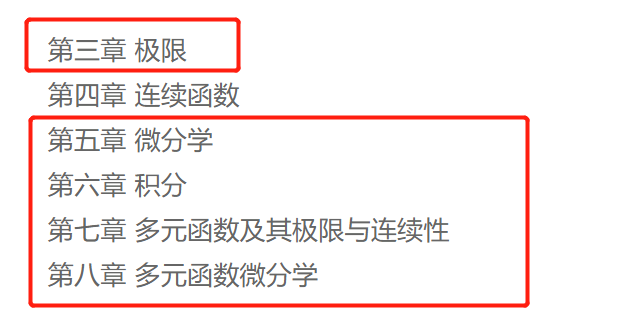

#### 8.5.1   符号表达式求极限

极限是微积分的基础，微分和积分都是“无穷逼近”时的结果。在 MATLAB 中， limit() 函数用于求表达式的极限。

该函数的调用格式如下：

- limit(F,x,a) ：当 x 趋近于 a 时表达式 F 的极限；

- limit(F,a) ：当 F 中的自变量趋近于 a 时F 的极限，自变量由 findsym() 函数确定。

- limit(F) ：当 F 中的自变量趋近于 0 时F 的极限，自变量由 findsym() 函数确定。

- limit(F,x,a,'right') ：当 x 从右侧趋近于 a 时F 的极限。

- limit(F,x,a,'left') ：当 x 从左侧趋近于 a 时F 的极限。

例如：

syms h n x
f = (log(x+h)-log(x))/h
L = limit((log(x+h)-log(x))/h,h,0)

求当 h 趋近于 0 时表达式 L 的极限，式中单引号可省略掉，结果为

L = 1/x

f = (1-x/n)^n
M=limit(f,n,inf)

求当 n 趋近于无穷大时表达式 M 的极限，结果为M = exp(-x) 或M = 1/exp(x)

## 例  求极限。

## (1) $$\mathop {\lim }\limits_{x \to 0} \left( {\frac{{\sin x}}{x}} \right) = ?$$

## (2) $$\mathop {\lim }\limits_{n \to \infty } \sqrt {n + \sqrt n }  - \sqrt n  = ?$$

解    程序如下：

(1)   

syms x;
f = sin(x)/x
limit(sin(x)/x)

ans = 1

(2)    

syms n;
f = sqrt(n+sqrt(n))-sqrt(n)
limit(sqrt(n+sqrt(n))-sqrt(n),n,inf)

ans = 1/2

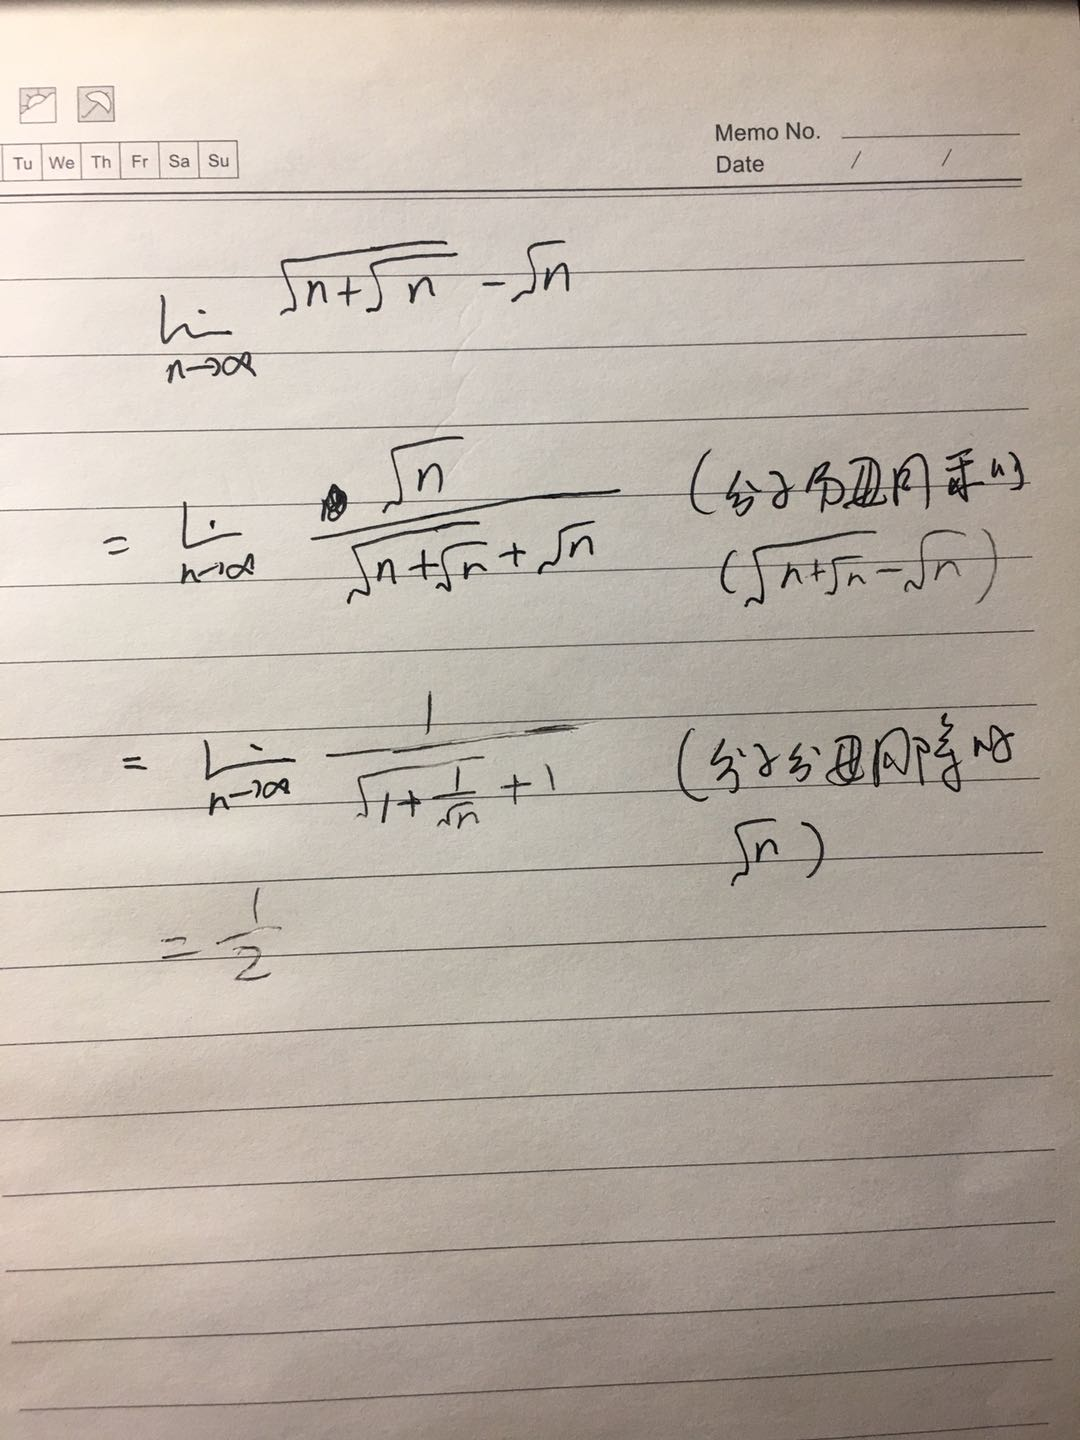

### 8.5.2   符号表达式导数、微分和偏微分

MATLAB 中使用 diff() 函数实现函数求导和求微分，可以实现一元函数求导和多元函数求偏导。当输入参数为符号表达式时，该函数实现符号微分，其调用格式如下：

- diff(S) ：对缺省变量求微分，实现表达式 S 的求导，自变量由函数 findvar() 确定。

- diff(S,v) ：对指定变量 v 求微分，该语句还可以写为diff(S,sym('v')) 。

- diff(S,n) ：求 S 的n 阶导数。

- diff(S,v,n) ：求S 对v 的n 阶微分 ( 导数) ，该表达式还可以写为 diff(S,n,'v') 。

## 例 8-5-2    符号导数和微分。

## (1)  已知$$y(x) = \sin (ax)$$， 求$$A = \frac{{dy}}{{dx}}$$为何值， $B=\textrm{y"}\left(x\right)$为何值。

## (2)  已知$$y(x) = \ln (1 + x)$$，$${\left. {\frac{{{d^2}y}}{{d{x^2}}}} \right|_{x = 1}}$$的值

解    程序如下：

(1)  

syms a x;    y=sin(a*x);
A= diff(y,x)
B = diff(y,x,2)

A = a*cos(a*x)

B = -  a^2*sin(a*x)

(2)  

syms x;
y=log(1+x)
d2y=diff(y,x,2)

d2y =-  1/(1+x)^2，即$$\frac{{{d^2}y}}{{d{x^2}}} =  - \frac{1}{{{{(1 + x)}^2}}}$$ 

然后将符号表达式转换成数值表达式：

x=1;eval(d2y)

ans = -  0.2500

即$${\left. {\frac{{{d^2}y}}{{d{x^2}}}} \right|_{x = 1}} =  - {\left. {\frac{1}{{{{(1 + x)}^2}}}} \right|_{x = 1}} =  - \frac{1}{4}$$    

## 例 8-5-3    已知$$z(x,y) = {e^{2x}}(x + {y^2} + 2y)$$ ， 求偏微分：$$a = \frac{{\partial z}}{{\partial x}}$$为何值，$$b = \frac{{\partial z}}{{\partial y}}$$为何值，$$A = \frac{{\partial^2 z}}{{\partial x^2}}$$为何值，$$B = \frac{{\partial^2 z}}{{\partial y^2}}$$为何值，$$AB = \frac{{\partial^2 z}}{{\partial x}{\partial y}}$$为何值。

解    程序如下：

syms x y;   
z=exp(2*x)*(x+y^2+2*y)

$$z = {\mathrm{e}}^{2\,x}\,\left(y^{2}+2\,y+x\right)$$

a=diff(z,x)

$$a = {\mathrm{e}}^{2\,x}+2\,{\mathrm{e}}^{2\,x}\,\left(y^{2}+2\,y+x\right)$$

b=diff(z,y)

$$b = {\mathrm{e}}^{2\,x}\,\left(2\,y+2\right)$$

A=diff(z,x,2)

$$A = 4\,{\mathrm{e}}^{2\,x}+4\,{\mathrm{e}}^{2\,x}\,\left(y^{2}+2\,y+x\right)$$

B=diff(z,y,2)

$$B = 2\,{\mathrm{e}}^{2\,x}$$

AB=diff(a,y)

$$AB = 2\,{\mathrm{e}}^{2\,x}\,\left(2\,y+2\right)$$

### 8.5.3   多元函数的导数与 jacobian() 函数

在MATLAB 中，多元函数的导数由 jacobian() 函数来实现。微积分中一个非常的重要概念为 Jacobian 矩阵，计算

函数向量的微分。 MATLAB 中， jacobian() 函数用于计算 Jacobian  矩阵。该函数的调用格式如下：

## R = jacobian(f,v) 。

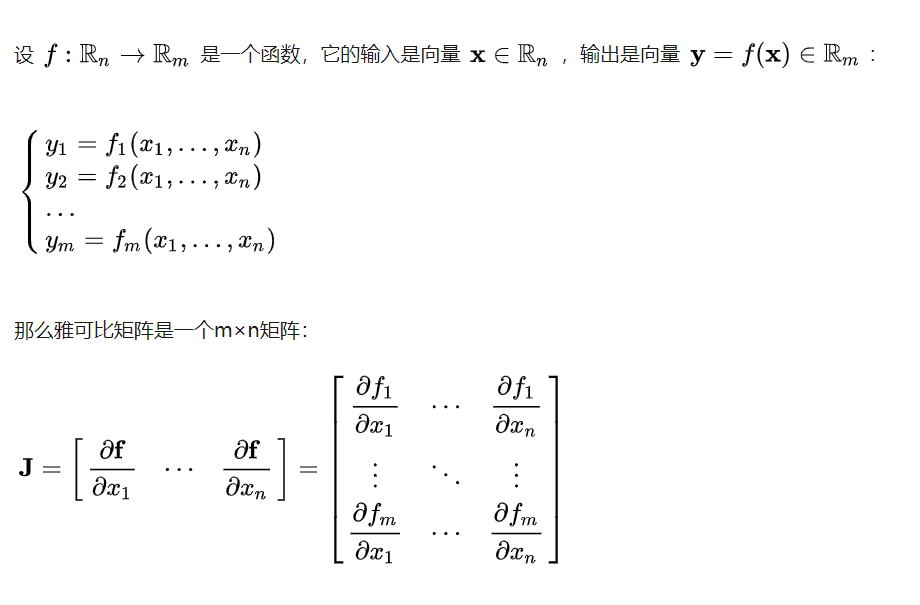

如果 f 是向量函数或函数， v 为自变量向量，则计算 f 的Jacobian 矩阵；如果 f 是标量，则计算f 的梯度，如果 v 也是标量，则其结果与 diff() 函数相同。

## 例    求$$\left\{ \begin{array}{l}
{x^2} + {y^2} = 4\\
{x^2} - {y^2} = 1
\end{array} \right.$$函数的 jacobi 矩阵。

解    程序如下：

x=sym('x');y=sym('y');z=sym('z');
jacobian([x^2+y^2; x^2-  y^2],[x,y])

$$ans = \left(\begin{array}{cc} 2\,x & 2\,y\\ 2\,x & -2\,y \end{array}\right)$$

ans =

[ 2*x,    2*y]

[ 2*x, -  2*y]

### 8.5.4   计算不定积分、定积分

与微分对应的是积分，在 MATLAB 中， int() 函数用于实现符号积分运算。该函数的调用格式如下：

- R = int(S) 。求表达式 S 的不定积分，自变量由 findsym() 函数确定；

- R = int(S,v) 。求表达式 S 对自变量 v 的不定积分；

- R = int(S,a,b) 。求表达式 S 在(a,b) 区间上的定积分，自变量由 findsym() 函数确定； a 为积分下限、 b 为积分

- 上限，上限、下限缺省时为不定积分。

- R = int(S,v,a,b) 。求表达式 S 在(a,b) 区间上的定积分，自变量为v 。

## 例  计算不定积分、定积分。

## (1)  $${f_1}(x) = \int {\frac{{{x^2} + 1}}{{{{({x^2} - 2x + 2)}^2}}}} dx$$ 

## (2)  $${f_2}(x) = \int_{{\rm{ }}0}^{{\rm{ }}\pi /2} {\frac{{\cos (x)}}{{\sin (x) + \cos (x)}}} dx$$    

## (3)  $${f_3}(x) = \int_{{\rm{ }}0}^{{\rm{ }} + \infty } {{e^{ - {x^2}}}} dx$$    

解  程序如下：

syms x
y1=(x^2+1)/(x^2-2*x+2)^2

$$y1 = \frac{x^{2}+1}{{\left(x^{2}-2\,x+2\right)}^{2}}$$

y2=cos(x)/(sin(x)+cos(x))

$$y2 = \frac{\cos\left(x\right)}{\cos\left(x\right)+\sin\left(x\right)}$$

y3=exp(-x^2)

$$y3 = {\mathrm{e}}^{-x^{2}}$$

f1=int(y1)

$$f1 = \frac{3\,\mathrm{atan}\left(x-1\right)}{2}+\frac{\frac{x}{2}-\frac{3}{2}}{x^{2}-2\,x+2}$$

f2=int(y2,0,pi/2)

$$f2 = \frac{\pi }{4}$$

f3=int(y3,0,inf)

$$f3 = \frac{\sqrt{\pi }}{2}$$

结果为

f1 = (3*atan(x - 1))/2 + (x/2 - 3/2)/(x^2 - 2*x + 2)

f2 = pi/4

f3 = pi^(1/2)/2

## 例     计算二重不定积分。

## (1)   $$\int\int {x{e^{ - xy}}}dxdy$$

## (2)   $$\int\int {\frac{{{y^2}}}{{{x^2}}}}dxdy$$,$\left(\frac{1}{2}\le x\le 2\textrm{，1}\le y\le 2\right)$

解    程序如下：

(1)   

syms x y
f=x*exp(-x*y)

$$f = x\,{\mathrm{e}}^{-x\,y}$$

F=int(int(f,x),y)

$$F = \frac{{\mathrm{e}}^{-x\,y}}{y}$$

F = 1/(y*exp(x*y))

$$F = \frac{{\mathrm{e}}^{-x\,y}}{y}$$

(2)  

syms x y;
f=y^2/x^2

$$f = \frac{y^{2}}{x^{2}}$$

int(int(f,x,1/2,2),y,1,2)

$$ans = \frac{7}{2}$$

ans =7/2